# Solution to the Problem of Applying Software Filtering to 1+10 kHz Mixed Signals

The following is a detailed description of a working solution to the signal filtering problem in the 2022 ENPH 253 robot competition.  Some of the math involved in the solution algorithm is explained, starting with the Discrete Fourier Transform and then moving onto an analogous treatment of the squarewave signal. 

The robot competition incorporated a 10 kHz infrared squarewave signal as a navigation beacon.  There was also a 1 kHz deceptive signal that would mislead an autonomous robot unable to differentiate between the two signals.  One of the required objectives of the course was to develop either a hardware or software solution to continuously apply a filter in order to reject the false beacon.

#### Fourier Analysis Primer

The solution takes inspiration from the discrete Fourier transform.  In the DFT, the incoming signal is multiplied into a matrix composed of vectors formed by using 'the roots of unity'. 

From Wikipedia:

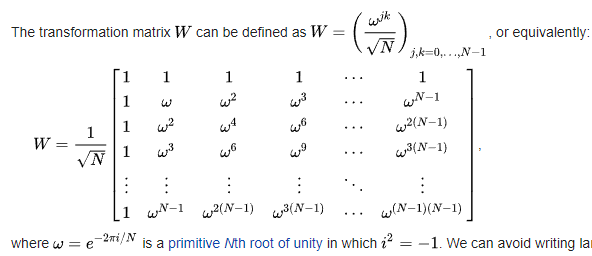

Math 307 UBC:

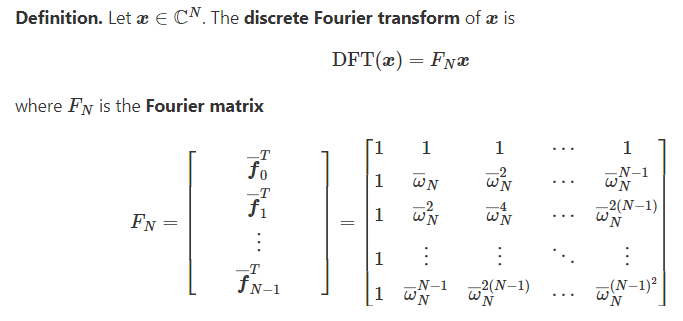

The basis vectors of the matrix encode the discrete version of Fourier sin and cosine vectors.  $\omega$ is the unit vector in the complex plane that has been rotated CW from the real-axis by $\frac{2 \pi}{N}$, such that after $N$ steps, it has made a complete revolution of the circle.  $\omega^2$ corresponds to two discrete rotation steps, $\omega^3$ to three, and so on.  With this information, notice that each horizontal vector in the matrix above represents 0,1,2,...,N-1 rotations around the unit circle in the complex plane, using evenly spaced discrete steps.

For example, the top vector is 0 rotations, the value remains as a blue vector not rotating, staying at <1,0> or $1+0*i$:

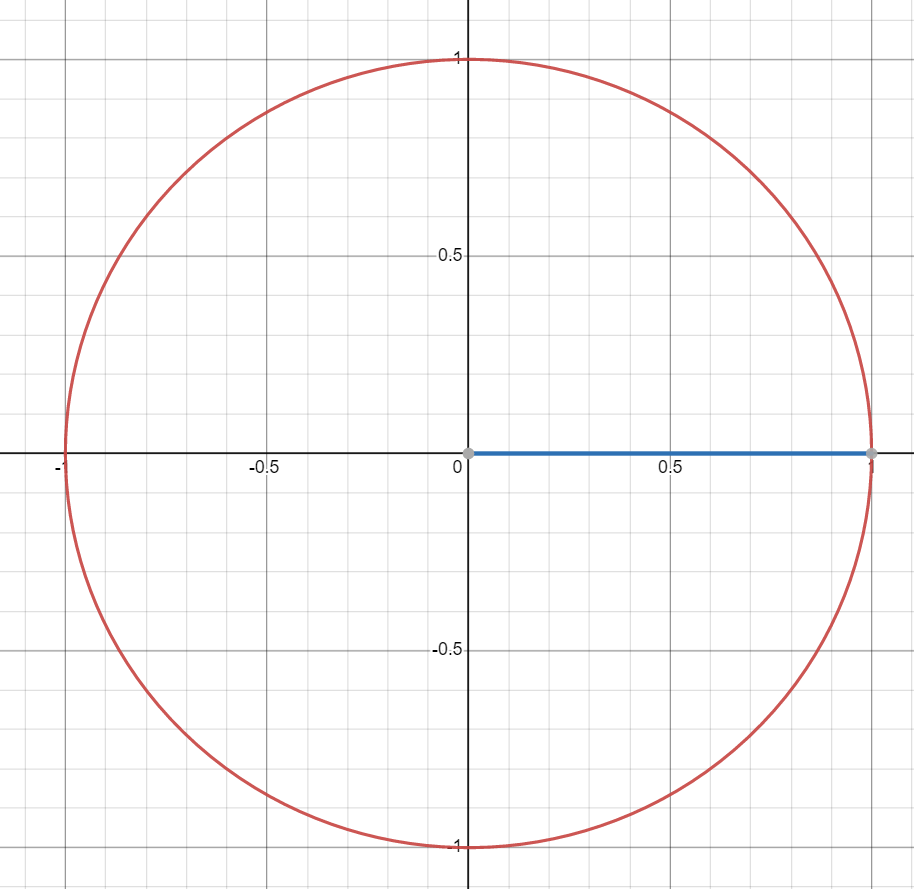

The next row rotates by $\frac{2 \pi}{N}$ for each step $\omega$, for N = 8 then the succesive complex numbers in vector form are:

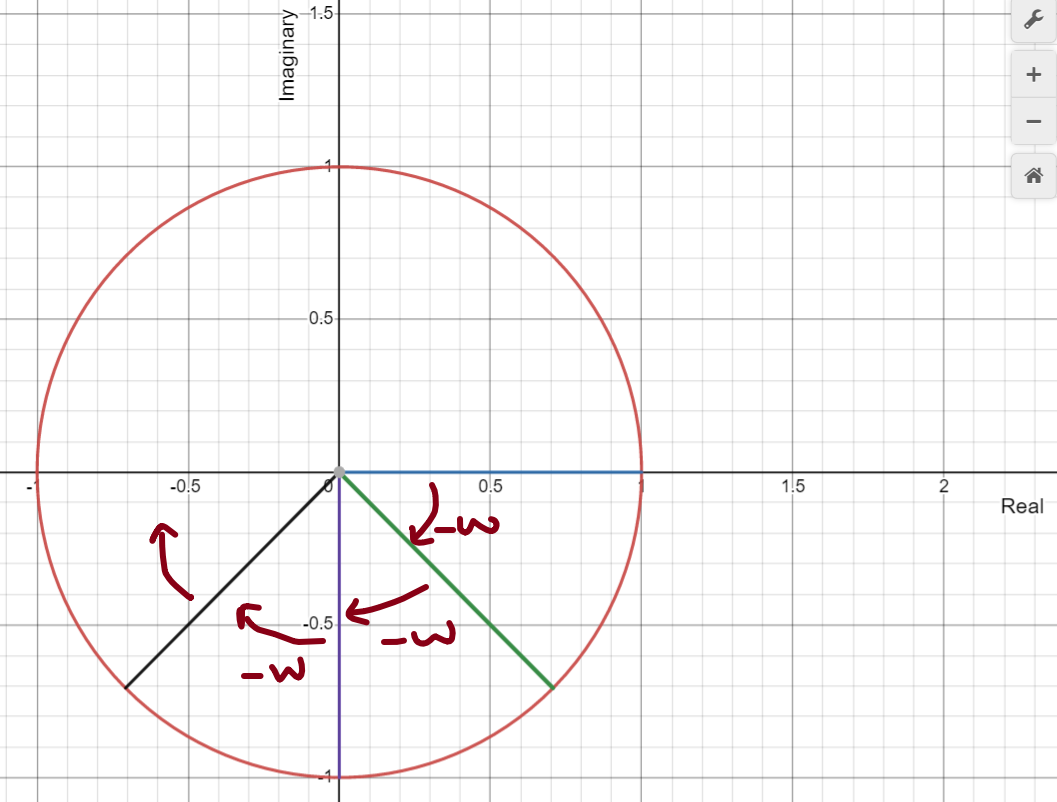

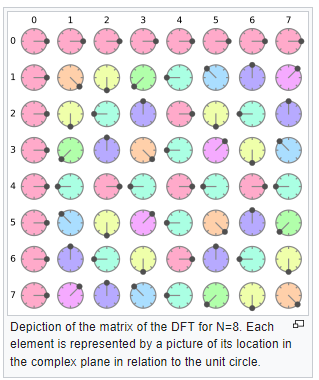

For the $j^{th}$ vector from the top we have

$\vec{v}_j=\cos(j \cdot\ 2 \pi \frac{k}{N}) - i \sin(j \cdot\ 2 \pi \frac{k}{N})$ for k=0 to k = N-1

This is very clever, we have the sin and cosine kept seperate by by using complex numbers.  As we know from continuous Fourier series, the Fourier basis vectors will be orthogonal to eachother and have a dot product of 0.  This same orthogonality can tease out the sinusoids from a discrete vector input to the DFT matrix.  The dot product of discrete values being the discrete version of the integral of the product of two functions.

 The result of the dot product of input $\vec{x}$ with a row vector when doing matrix multiplication is as follows.  

$\vec{v}_j\cdot\vec{x} = a + bi$ where $a$ is real and represents the projection/dot onto the cosine portion of the jth frequency of the DFT basis vector, and $b$ is the portion dotted onto the sine element.

The numerical values for $a$ and for $b$ indicate the amount of sine or cosine oscillation at frequency $f_j$ represented by the $j^{th}$ row vector.  The dot product returns the amplitudes of the sine and cosine elements from the signal that match at that frequency.

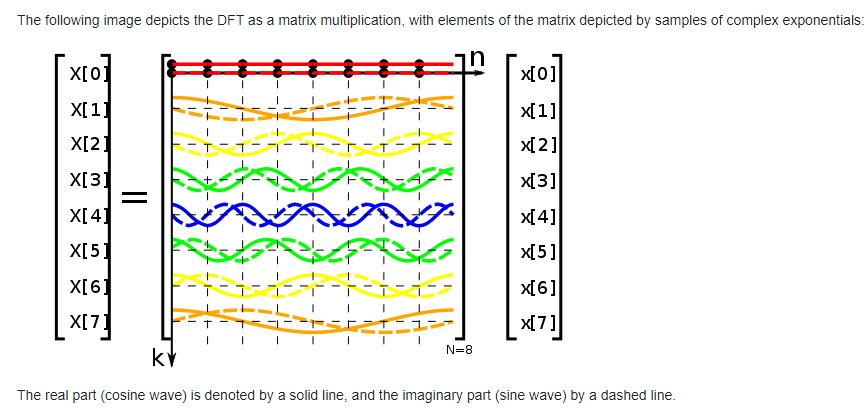

Recalling the identity $\sqrt{A^2+B^2}\sin(x+\arctan (B/A))=A\cos(x)+B\sin(x)$ We can see how we might determine the amplitude and phase of a sinusoidal input vector that has a phase offset based on the results from the transform.  With complex numbers of the DFT, it translates to $\frac{|a+bi|}{N}$ being the amplitude of the input at that jth frequency.  Due to the number of samples in the vector, we need to normalize to amplitude by dividing by $N$ as shown above and then we are done.  The phase ofset is $\arctan(b/a)$, which corresponds to $arg(a+bi)$. 

# Back to the Infrared Beacon Problem

For the case of sampling and filtering signals from infrared beacons, the DFT works great, but using the entire matrix is computationally expensive and also unecessary.  The signals from the beacons are also square waves, which can hold smaller amplitude harmonic frequencies in them.  We are primarily interested in the 1kHz and 10kHz frequencies, so in essence, we can completely ignore all the other basis vectors in a DFT matrix.  If we only focus on the 10kHz signal, then the problem is reduced to a single complex vector.

The programming language does not have an implemntation of complex numbers, but as we have seen the vector we desire is actually 

$\vec{v}_{10kHz}=\cos( 2 \pi \frac{k}{N}) -  i\sin(2 \pi \frac{k}{N})$ for k=0 to k = N-1

Where N is the number of samples being taken and $j$ is used to normalize the angular frequency to match that of a 10kHz wave, based on the sampling frequency (number of microseconds between each sample).  N should provide a complete number of cycles to be a proper Fourier basis, a safe bet is multiples of 100 since the period for 10kHz is 100 $\mu s$.  We choose N as follows: $N=\frac{T}{\delta t}\cdot n_{cycles}$ where T is the period, $100\mu s$, $\delta t$ is the sample rate (could be $20 \mu s$ for example) and n is the number of cycles.  If we choose an N that is a multiple of 100, then for any selected integer $\delta t$, we can be sure there is an integer number of cycles as well and that it is a valid Fourier basis.

We note that $\vec{x} \cdot (\vec{a}+\vec{b})=\vec{x} \cdot \vec{a} + \vec{x} \cdot \vec{b}$ so we can perform the sin and cosine dot products seperate using real numbers to get the real and complex values.   Then we divide by N, and apply $\sqrt{A^2+B^2}$ principle to the two dot products and we have exactly what we want, the DFT for the 10kHz signal at a low computational cost.

#### Minimizing microcontroller resources

The limited memory on a microcontroller makes it difficult to store large buffers of analog read values.  There is an easy solution to this difficulty, we can continuously calculate the dot product as we read analog values, negating the need to store them.  If we can match each analog read value with the corresponding Fourier basis vector element value as we read, then we can compute the dot product using an accumulator.

Observe:

Suppose I have a reference vector <1,2,3,4> and I want to read 4 values and dot product them with it.  A non-memory restricted approach would read the values <a,b,c,d> and then dot the two vectors.  But really what we want and what the computer does is 1*a + 2*b + 3*c + 4*d.  The solution is to assign an accumulator, call it dotP.  Then we initialize:

dotP = 0;

r = readval();

dotP = dotP + r*1;  

r = readval();

dotP = dotP + r*2;  

r = readval();

dotP = dotP + r*3;  

r = readval();

dotP = dotP + r*4; 

We have taken four readings and doted them with the vector <1,2,3,4> and we did this without storing intermediate vlaues.

Now we no longer need to store a large array of size N with all the analog read values, we just keep track of the accumulator dotP.  So this can be done for both the sine and cosine portions of the Fourier basis vector for 10kHz to get our desired values.

Similarly our reference signal only needs to cover one period of the 10kHz signal.  For example we could make an array of 100 evenly spaced values from 0 to 99 of sin() to account for every possible discrete step, since our minimum time reading with the Arduino is down to microseconds and the period is 100 microseconds.  Then cosine will be offset by 25us.  If we have a large number of samples, like 1000 samples, we don't need to compute the entire DFT vector, since the vector will be periodic by nature.  Precomputing these values and storing them in a array during setup is practical.

#### Overcoming sample rate issues 

With the problem constraint that we only care about the 10kHz signal, we can even move beyond the restriction of having faster sample rates than the signal period.  For exaple, a $110\mu s$ sample rate will appear as though we are reading the 10kHz signal at $110-100=10 \mu s$ sample rate.  

The caveat is that al signal that is 10 cycles of $110 \mu s$ in period, or $1.1ms$ period would appear identical, this would correspond to a 909 Hz signal.  This will always be a problem of sorts for the DFT, it can pick up ghost signals that lie outside of its discrete bounds.  But given the strength of the signal we are looking for, we can be sure that other frequencies are not going to produce nearly as large of amplitudes (except for 1kHz).

This concludes the description of a focused DFT algorithm that is fast and low memory usage.

# Square Wave Analysis

Taking inspiration from the fourier methods we can try to come up with an analagous way of dealing with a square wave signal at a focused frequency. We can create a single period 10kHz square wave reference first, the same as the sin and cos references of the DFT.  Then we read analog values and dot product them with our square references.  However the trigonometric identity we used earlier does not translate over quite as well.

What does translate quite well is the concept of orthoganality.  It can be shown that for squarewaves that have frequencies matching the DFT, they will all have orthogonal vectors.  This means that we can filter out other square wave signals, including DC signals completely, by using the same procedure as the DFT.

The correlation with a square wave against the reference based on phase offset is given as follows for the discrete set of 100 points correlating to one period, such as the case of the 10kHz wave discretized to $1 \mu s$.  The algorithm implemented works by creating a single-period reference of an expected 10kHz signal with a phase shift phi of 0.  Note that MatLab indexing starts at 1.

Also note, the implementation of the square wave reference in Arduino is not an array, but simply a logic sequence choosing 1,0,-1 depending on how much time has passed, the phase offset, and where in the squarewave cycle that sample would fall.

(See further below for function definitions of offSetSquare() )

%Number of discrete samples in reference wave
N=100; 
% Create a reference with 0 phase shift (the top of square wave starts at first index value)
ref = offSetSquare(0,N);
plot(ref)
hold on


An important step in the algorithm is that it is calculating a dot product of the analog input signal against the reference.  But we have no way of knowing what the phase offset is between the two.  The result is that with a single dot product normalized by 2N, depending on the amount of phase shift between signal and reference, we may not detect any correlation at all.  We take the absolute value which is $abs(x) = \sqrt{x^2}$ to return a positive amplitude.  As can be seen we have a problem of an extremely variable correlation based on what the phase offset might be

squareDot = zeros(1,N);
for i=1:N
    squareDot(i)=dot(ref,offSetSquare(i,N));
end

%Normalize back to amplitude match
squareDot = squareDot/N;
plot(squareDot);
y1= abs(squareDot);

title("Signal to reference correlation based on phase offset")
xlabel("Phase Offset (microseconds)");



But we can fix this.  Recal that the DFT uses both sin and cosine to remove any dependency on phase offset.  Note that for 10kHz the sin and cos functions have a $25 \mu s$ offset.  We can try to implement the same procedure with our square wave.

## Root Sum of Squares

The amplitude of the DFT is determined by taking the pythagorean root of the sum of squares for the sin and cos offsets.  We can apply a similar procedure to the square wave, but without limiting ourselves to only two offsets.  We can apply a procedure similar to cross correlation by taking the root of the sum of squares of many correlations from various assumed phase offsets.

Note that because of the symmetry of the wave and the squaring of the correlation values, only the first N/2 of phase shift is important, since a phase shift of +N/2 gets us back to where we started but inverted, and we are dealing with squared values (absolute vals).  With some computation and testing, we can see that we do not end up with a smooth response to phase shift with only a 0 and 25 offset, so we generalize the procedure to allow for multiple evenly spaced offsets.

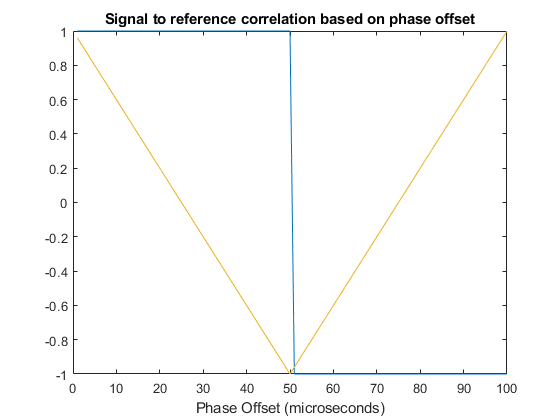

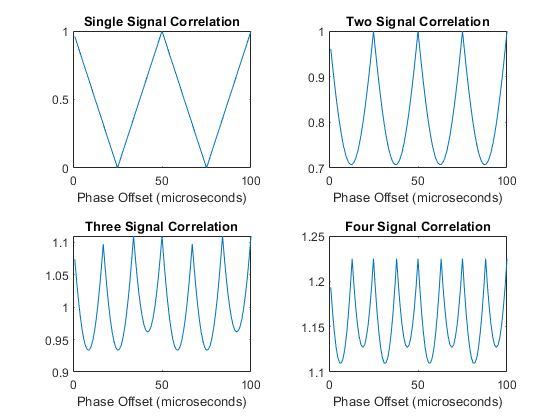

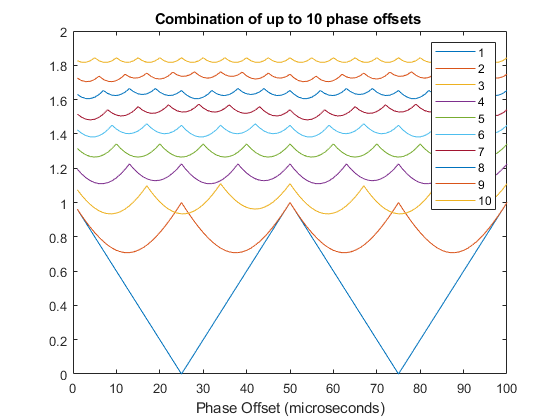

plotMultiplesOfOffsets();

Actually what we really would like from a good filter is stability, which we can quatify as the percent deviation froom the maximum reading as the reference signal is phase shifted.  We can see that the stability rapidly increases as we add more phase comparisons.  At 50, the signal reading becomes completely stable.  In reality, the phase shift of the reference signal is not discretized, so we would not expect to reach 0.  But something like $\pm 5 \%$ is something that we can likely live with for the scope of our needs, and that is already reached at just 4 parallel samples (signal correlations).  

In actual practice, only two samples does indeed give a 30% error from peak value dependent on phase shift.  But moving up to 4 reduces it to a stable and acceptable level.

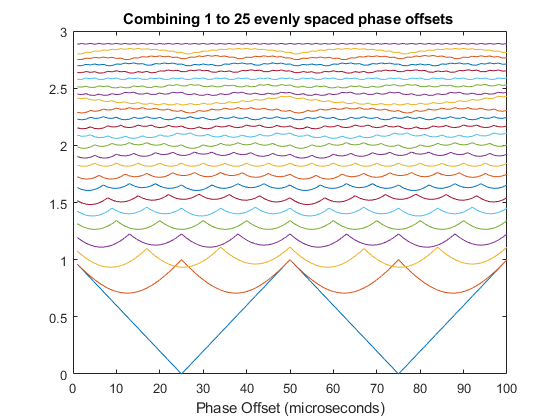

f = figure;
plot(y1)
hold on
num = 25;
spread = [1 zeros(1,num-1)];
for i = 2:num
    vec = sampleCorrelate(squareDot, i, N);
    spread(i)= 1-min(vec)/max(vec);
    plot( vec)

end
title("Combining 1 to 25 evenly spaced phase offsets ")
xlabel("Phase Offset (microseconds)");

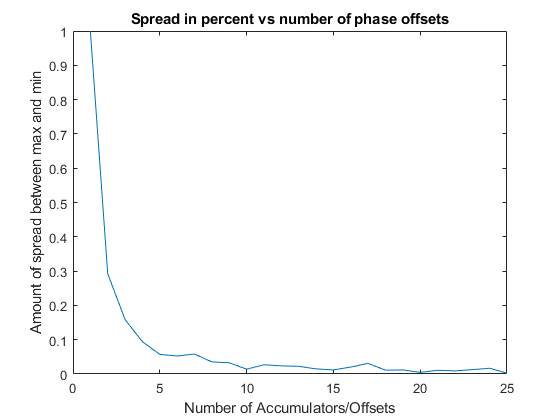


f = figure;
plot(spread)
title("Spread in percent vs number of phase offsets")
xlabel("Number of Accumulators/Offsets");
ylabel("Amount of spread between max and min")

To conclude, we can make a low-memory fast DFT analog for the square wave by using an algorithm that provides the following features:

- Low memory reference signal, square wave

- Use of accumulators to elimate signal buffer array

- Only computes the desired frequency amplitude, instead of all frequencies

The testing results with a single 100 Ohm resistor and bare, unfiltered IR phototransistor signal indicates complete filtering of the 1kHz signal.  With 500 samples taken at 7 microsecond intervals, the total read time is 3.5 ms.  This results in virtually no noise or DC leakage and a clear, stable amplitude reading of the incoming 10kHz squarewave.  As such, the described 4 accumulators method for frequency filtering is recommended for the project for speed and reliability. 

# Example of Algorithm at Work

The software filter works best with larger numbers of samples (100-500), but for the purpose of demonstrating the algorithm, consider the case of $5$  samples taken with a sampling interval of $20 \mu s$.  We can use the modulus function to continually map the offests to a position of 1 or -1 on the reference square wave, as shown in the mapping below.

Assume we have a sequence of readings of the IR signal as follows [ 20, 20, 0, -15, -25], and that the sample interval is  $20 \mu s$

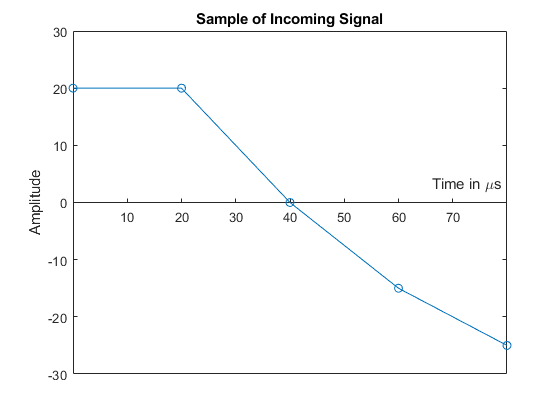

figure
signal = [ 20, 20, 0, -15, -25];
sampleTime = 0:20:80;

plot(sampleTime,signal,'-o')
title('Sample of Incoming Signal')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-30,30];
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

 Then the algorithm works as follows:

- Assign four evenly spaced phase offsets, rounded to the nearest integer microsecond: [0,13,25,38], assign labels A,B,C,D to these

- Take the first reading at $t=0 \mu s$, 20

- All four offsets are situated at a value of 1 on the reference signal so we add the values to their accumulators:

- A = 20; B = 20; C = 20; D = 20

- Take the second reading at $t=20 \mu s$, 20

- The D offset references to -1 now so it is subtracted, while the others are added

- A = A + 20 =40  ; B = B + 20 = 40 ; C = C + 20 = 40; D = D - 20 = 0

- Take the third reading at $t=40 \mu s$, 0

- All offsets remain the same regardless of referencing

- Take the fourth reading at $t=60 \mu s$, -15

- All four signals reference to the -1 portion of the squarewave

- A = A - 20 =20  ; B = B - 20 = 20 ; C = C - 20 = 20; D = D - 20 = -20

- Take the fifth reading at $t=80 \mu s$, -25

- C,D reference to 1 while A,B reference to -1 now

- A = A + 25 =45  ; B = B + 25 = 45 ; C = C - 25 = -5; D = D - 25 = -45

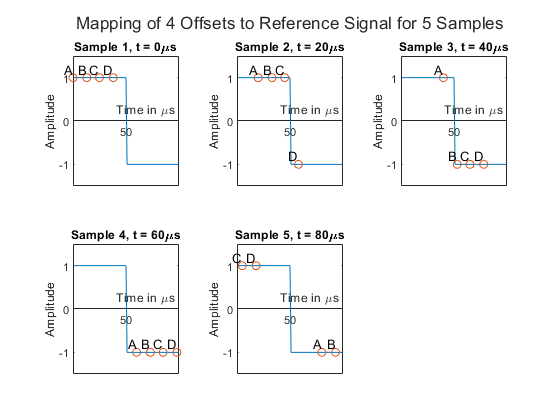

showSampleReferences();

 The final values for A, B, C, D are the dot products of the readings versus an amplitude 1 square wave, the only difference being the phase offset for each.

A = 45, 

B = 45, 

C = -5, 

D = -45

 We take the root mean square and to get a normalized value we use the multiplier $\frac{2}{N}$:

rms([45,45,-5,-45])*2/5

This is interesting the amplitude returned is 15.6 which is a rough match for the signal samples that have a resemblance to a 10kHz squarewave:

figure

ans =   15.620499351813308


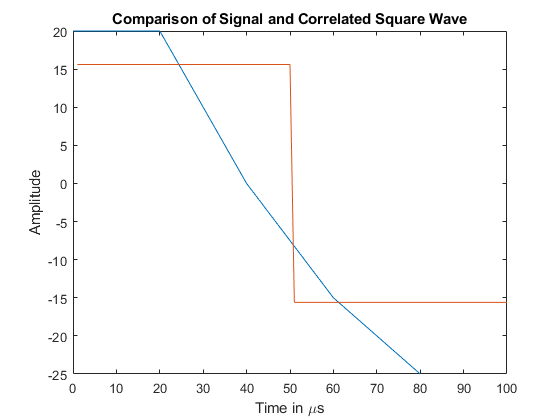

signal = [ 20, 20, 0, -15, -25];
sampleTime = 0:20:80;

plot(sampleTime,signal)
hold on
plot(ref*15.6);
title('Comparison of Signal and Correlated Square Wave')
ax = gca;
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';


% Create a 10kHz square wave signal that is offset by Phi microseconds.

function  vec = offSetSquare(phi,N)
vec = -1*ones(1,N);
if (phi < N/2)
    vec((phi + 1):(phi+N/2)) = 1;
else
    vec((phi + 1):N) = 1;
    vec(1:(phi-N/2)) = 1;
end

end


% Gives a theoretical response pattern  based on the number of parallel samples
% being correlated and normalized together.  The samples are arranged so that
% their phase shift is spread evenly between 0 and N/2
function vec = sampleCorrelate(squareDot, nsample, N)

vec = zeros(1,N);
for i=1:N
    sum = 0;
    % Take the sum of squares for the expected dot product of each parallel
    % sample.  The phase offset from the reference is given from 0 to 100
    for j = 0:(nsample-1)
        sum = sum + squareDot(mod(floor((j/nsample)*(N/2) - 1 + i),N) + 1)^2;
    end
    % The square root of the squares gives a normalized average
        vec(i)=sqrt(sum);
end

end



function plotMultiplesOfOffsets()
N=100;
ref = offSetSquare(0,N);
squareDot = zeros(1,N);
for i=1:N
    squareDot(i)=dot(ref,offSetSquare(i,N));
end

%Normalize back to amplitude match
squareDot = squareDot/N;
plot(squareDot);
y1= abs(squareDot);

title("Signal to reference correlation based on phase offset")
xlabel("Phase Offset (microseconds)");
% Plot cases for injecting more samples to smooth readings
y2 = sampleCorrelate(squareDot, 2, N);
y3 = sampleCorrelate(squareDot, 3, N);
y4 = sampleCorrelate(squareDot, 4, N);


% Create plots
t = tiledlayout(2,2);
nexttile
plot(y1)
title("Single Signal Correlation")
xlabel("Phase Offset (microseconds)");
nexttile
plot(y2)
title("Two Signal Correlation")
xlabel("Phase Offset (microseconds)");
nexttile
plot(y3)
title("Three Signal Correlation")
xlabel("Phase Offset (microseconds)");
nexttile
plot(y4)
title("Four Signal Correlation")
xlabel("Phase Offset (microseconds)");


figure
plot(y1)
hold on
num = 10;

for i = 2:num
    vec = sampleCorrelate(squareDot, i, N);
    plot( vec)
end
title(['Combination of up to ' num2str(num) ' phase offsets ']);
legend(["1" "2" "3" "4" "5" "6" "7" "8" "9" "10"]);
xlabel("Phase Offset (microseconds)");
end


function showSampleReferences()
figure
t = tiledlayout(2,3);

t.Title.String = 'Mapping of 4 Offsets to Reference Signal for 5 Samples';
nexttile
%Number of discrete samples in reference wave
N=100; 
% Create a reference with 0 phase shift (the top of square wave starts at first index value)
ref = offSetSquare(0,N);
p = plot(ref);
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-1.5,1.5];
ax.Title.String = "Sample 1, t = 0\mus";
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

refX = [0 13 25 38];
refY = [1 1 1 1];
labels = {'A','B','C', 'D'};
plot(refX,refY,'o')
text(refX,refY,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

nexttile
p = plot(ref);
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-1.5,1.5];
ax.Title.String = "Sample 2, t = 20\mus";
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

refX = [0 13 25 38] + 20;
refY = [1 1 1 -1];
labels = {'A','B','C', 'D'};
plot(refX,refY,'o')
text(refX,refY,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

nexttile
p = plot(ref);
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-1.5,1.5];
ax.Title.String = "Sample 3, t = 40\mus";
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

refX = [0 13 25 38] + 40;
refY = [1 -1 -1 -1];
labels = {'A','B','C', 'D'};
plot(refX,refY,'o')
text(refX,refY,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

nexttile
p = plot(ref);
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-1.5,1.5];
ax.Title.String = "Sample 4, t = 60\mus";
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

refX = [0 13 25 38] + 60;
refY = [-1 -1 -1 -1];
labels = {'A','B','C', 'D'};
plot(refX,refY,'o')
text(refX,refY,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

nexttile
p = plot(ref);
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YLimMode='manual';
ax.YLim = [-1.5,1.5];
ax.Title.String = "Sample 5, t = 80\mus";
ax.YLabel.String = 'Amplitude';
ax.XLabel.String = 'Time in \mus';

refX = mod ([0 13 25 38] + 80, 100);
refY = [-1 -1 1 1];
labels = {'A','B','C', 'D'};
plot(refX,refY,'o')
text(refX,refY,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

end